inputArg1 = 20

inputArg1 = 20

inputArg2 = 15

inputArg2 = 15

inputArg3 = 'Q15R20'

inputArg3 = 'Q15R20'

%UNTITLED5 Summary of this function goes here
%   Detailed explanation goes here
s=tf('s');
l = 0.092;
m_R = 0.412;
J_R = 8.9*10^-3;
B_R = 2.2*10^-3;
m_H = 0.220;
J_H = 0.694*10^-3;
B_H = 0.199*10^-6;
g = 9.82;

p1 = (-B_R) / (J_R-m_H*l^2);
p2 = B_H / (J_R-m_H*l^2);
p3 = (l*(m_R+m_H)*g) / (J_R-m_H*l^2);
p4 = 1 / (J_R-m_H*l^2);
p5 = 1 / J_H;
p6 = B_H/J_H;

A = [0 1 0 ; p3 p1 p2 ; -p3 -p1 -(p6+p2)];
B = [0 ; -p4 ; p5+p4];
C = [1 0 0 ; 0 1 0 ; 0 0 1];
D = zeros(3,1);

tt = A + .5*eye(3);

v = [-6.2405 + 2.3051i;-6.2405 - 2.3051i;-1.3202 + 0.0000i];

otherk = place(A, B, v)

otherk =    -1.0000   -0.1005   -0.0005


k2=place(A,B,[-1.1536;-0.1998;-0.0015]);
Acl = A-B*k2;

Q = [1.62*inputArg1 0 0;
     0 13*10^-3 0;
     0 0 2.53*10^-6];
R = 15.84*inputArg2;

[k, S, e] = lqr(A, B, Q, R);
inputArg3

inputArg3 = 'Q15R20'

k

k =    -1.2679   -0.1328   -0.0001



Ac2 = A-B*k;
eigenvalues1=eig(Acl)

eigenvalues1 =    -1.1536
   -0.1998
   -0.0015


eigenvalues2=eig(Ac2)

eigenvalues2 =   -9.4435 + 2.7285i
  -9.4435 - 2.7285i
  -0.1248 + 0.0000i


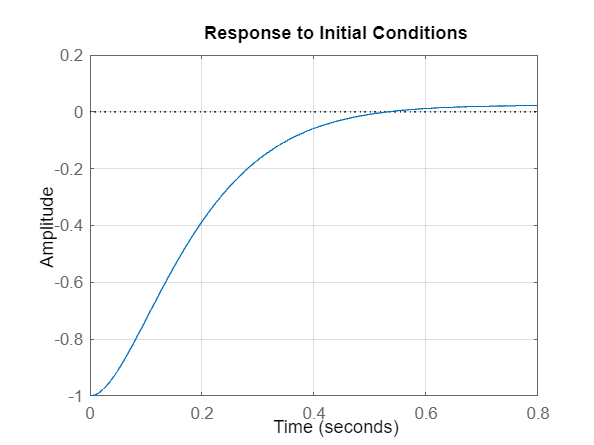

G = ss(A-B*k,B,C,D);
SettleMax=1*0.05;
SettleMin=-1*0.05;

figure()
initial(G(1,1),[-1 0 0])
grid on

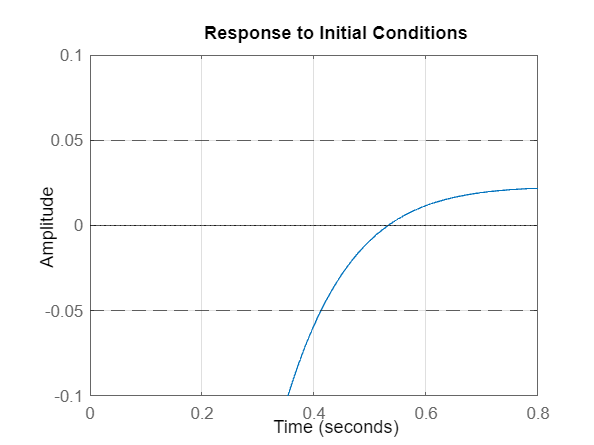


figure()
initial(G(1,1),[-1 0 0])
ylim([-0.1 0.1])
yline(0)
yline(SettleMax,'--')
yline(SettleMin,'--')
grid on